# Reeksamen F15

## ***Opgave 3.***

#### *Opgave 3.A:*

clear all
format short e
y = [0 57 95 141 182 230 285 351 418 491 567 646 712];
t = [0 31 59 90 120 151 181 212 243 273 304 334 365];

n = length(y);
p = polyfit(t,y,n-1)

p =   -6.9696e-24   1.5001e-20  -1.4240e-17   7.8506e-15  -2.7853e-12   6.6575e-10  -1.0901e-07   1.2176e-05  -9.0402e-04   4.2183e-02  -1.1051e+00   1.3847e+01  -1.9803e-07


#### *Opgave 3.B:*

Til interpolationen anvendes Matlabs indbyggede funktion interp1. Funktionen tager ind fokus værdier, den de tilhørende værdier til fokus

værdierne & værdien blandt fokus værdierne, som der skal interpoleres til. Dagene er vores fokus værdier, hvor de tilhørende data er nedbørsmængden, hvortil vi ønsker at interpolere en nedbørsværdi til dag 100.

format short
Nedboer_interpolation = interp1(t,y,100, "linear")

Nedboer_interpolation = 154.6667

#### ***Opgave 3.C:***

Nedboer_spline = spline(t,y,100)

Nedboer_spline = 154.8729

#### ***Opgave 3.D:***

For at kunne plotte punkterne på en line, skal vi først have oprettet en spline for alle punkterne.

Dette gøres ved at oprette enten et linspace der har intervallet 0-365 eller ved oprettelsen af en tidsvektor, der tager start enheden, interval og slut værdien: 0:1:366-1.

Til udførslen af opgaven er det linspace, som oprettes:

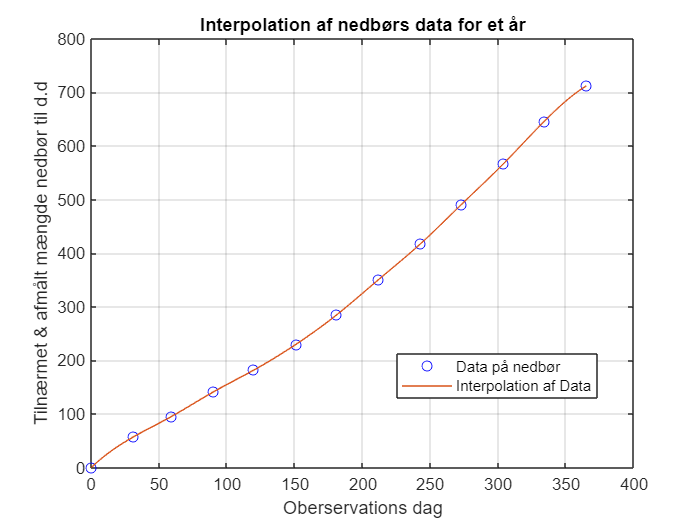

dage = linspace(0,365,366);
not_a_knot = spline(t,y,dage);

plot(t,y,'bo','DisplayName','Data på nedbør')
hold on
plot(dage,not_a_knot, 'DisplayName','Interpolation af Data')
legend('Location','best')
xlabel('Oberservations dag')
ylabel('Tilnærmet & afmålt mængde nedbør til d.d')
title('Interpolation af nedbørs data for et år')
grid
hold off

#### ***Opgave 3.E:***

Svar på denne underopgave vil forekomme under plottet:

% Afvigelsen mellem spline & den lineære interpolation:
Forskel_Inter_Spline = ((Nedboer_spline/Nedboer_interpolation)-1)

Forskel_Inter_Spline = 0.0013

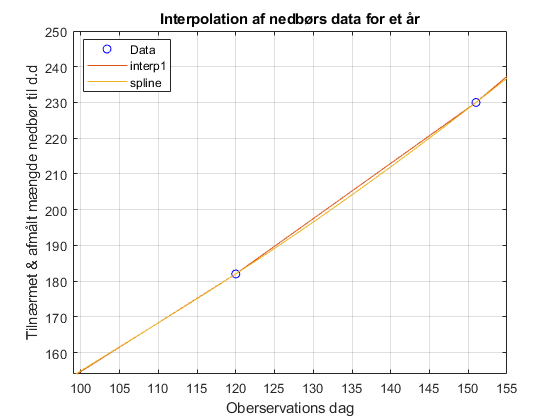

dage1 = linspace(0,365,366);
not_a_knot1 = interp1(t,y,dage, "linear");

plot(t,y,'bo', 'DisplayName','Data')
hold on
plot(dage1,not_a_knot1, 'DisplayName','interp1')
hold on
plot(dage,not_a_knot, 'DisplayName','spline')
legend('Location','best')
xlabel('Oberservations dag')
ylabel('Tilnærmet & afmålt mængde nedbør til d.d')
title('Interpolation af nedbørs data for et år')
grid
hold off
xlim([99 155])
ylim([154 250])

Afvigelsen mellem de to metoder på dag 100 er: 0,13%. Hvilket ikke fortæller meget om, hvilken metode, der er til at foretrække frem for den anden.

Derfor inddrages en motificeret version af grafen fra underopgave d.

Der vælges at inplementere en kurve for den lineæreinterpolation, så resultaterne kan sammenlignes.

Kigges der på data-kurverne fra dag 100-150, så er det tydligt at se, hvordan den lineæreinterpolation (interp1) viser sig i form af en lineær forbindelse mellem hver af observations dagene. Ses der på spline-interpolationen; dannes et mere realistisk billede af mængden af regn, da mængden af regn her fremkommer svigende. 

Derfor vurderes spline som værende den foretrækkende interpolationsmetode til denne type data. 

# Ordinær Eksamen E18

## ***Opgave 3.***

#### *Opgave 3.A:*

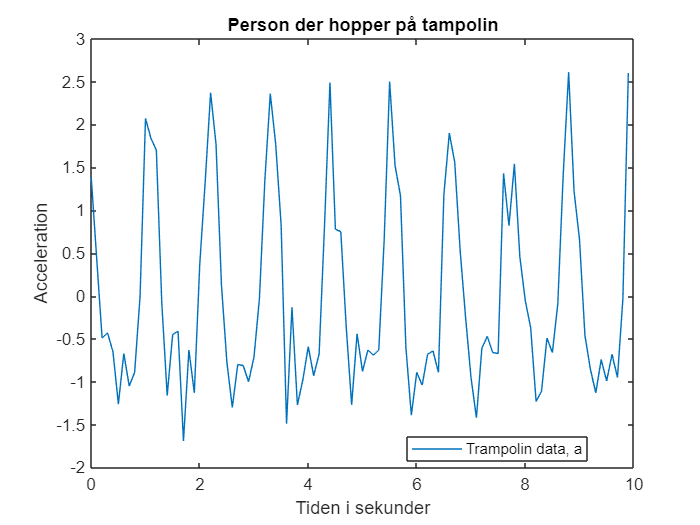

clear all
a = [ 1.38  0.44 -0.49 -0.43 -0.65 -1.26 -0.67 -1.05 -0.89  0.00 ...
      2.07  1.84  1.70 -0.08 -1.16 -0.45 -0.41 -1.69 -0.63 -1.13 ...
      0.37  1.33  2.37  1.77  0.13 -0.77 -1.30 -0.80 -0.81 -1.00 ...
     -0.71 -0.03  1.35  2.36  1.77  0.83 -1.49 -0.13 -1.27 -0.98 ...
     -0.59 -0.93 -0.68  0.82  2.49  0.78  0.75 -0.36 -1.27 -0.44 ...
     -0.88 -0.63 -0.69 -0.63  0.66  2.50  1.52  1.17 -0.60 -1.39 ...
     -0.89 -1.04 -0.68 -0.64 -0.89  1.18  1.90  1.56  0.53 -0.25 ...
     -0.95 -1.42 -0.61 -0.47 -0.66 -0.67  1.43  0.82  1.54  0.46 ...
     -0.05 -0.37 -1.23 -1.11 -0.49 -0.66 -0.09  1.42  2.61  1.22 ...
      0.66 -0.46 -0.85 -1.13 -0.74 -0.99 -0.68 -0.95 -0.03  2.60 ];

% Matricen a indeholer 100 mållinger.
% Da der er 0.1 sec. mellem hver målling, så er den totale tid = 100 * 0.1 -> 10 sec.
% Tidsvektoren kan bestemmes på forskellige måder, men de 3 udtænkt til
% denne opgave er:

    % Et linspace hvor a(t_1) = 1.38, t_1 = 0 og slut tiden 10.
t1 = linspace(0,length(a)/10);
    % En tidsvektor a(t_1) = 1.38, t_1 = 0, hvor slut tiden bliver 9.9 sek.
t2 = 0:0.1:10-0.1;
    % En tidsvektor a = 1.38, t = 0, hvor slut tiden bliver 9.9 sek.
t3 = 0:0.1:(length(a)/10-0.1);

% Tidsvektor t2 bliver valgt til udførslen af plottet (kunne også have
% været t3), da tidsintervallet i t1
% mellem hver målling på linspace ikke er i overensstemmelse med det
% beskrevede tidsinterval i opgavebeskrivelsen, Delta_t = 0.1.
plot(t2,a,'DisplayName','Trampolin data, a')
hold on
legend('location', 'best')
title('Person der hopper på tampolin')
xlabel("Tiden i sekunder")
ylabel("Acceleration")
hold off

Eftersom at vi starter på en top, og slutter med en top, så kan vi finde den anslåede dominerende svingning ved at tælle toppene og dividere mængden med tidsintervallet. Hvis start og slut top inddrages, så får vi 9 toppe:


$$f = \frac{9}{10 s} = 0.9Hz$$


#### *Opgave 3.B:*

dt = 0.1;                                % Samplingsinterval (s)
n = length(a);                        % Antal samplinger
T = n*dt;                             % Signallængde (s)
t = (0:n-1)*dt;                       % Tidsvektor (s)
fs = 1/dt;                            % Samplingsfrekvens (Hz)
fmax = fs/2;                          % Maks frekvens (Hz)
df = 1/T;                             % Frekvensstep (Hz)
f = (0:n-1)*df;                       % Frekvensvektor (Hz)
Y = fft(a)/n;                         % FFT af a
P = real(Y).^2 + imag(Y).^2;          % Powervektor
res = find(P==max(P))                 % Finder maksimale powervektor.

res =     10    92


% Det viser sig, at der er to maksimale powervektorer; en positiv og negativ.
% Da vi fokuserer på de positive svingninger, så anvendes den første res af de to powervektorer.
Den_dominerende_svingning = f(res(1)) 

Den_dominerende_svingning = 0.9000

Den dominerende frekvens ved FFT viser, at frekvensen er:


$$f(res(1)) = (0:res(1)-1)*df \rightarrow f(res(1)) = (0:10-1)*0.1 = 0.9 Hz$$
